# Proyecto 3 - Luna

## Planteamiento

El propósito del proyecto consiste en simular y modelar el movimiento lunar en relación a la Tierra y el Sol, con el fin de resolver la incógnita sobre si la Luna orbita alrededor de la Tierra o del Sol. También habrá que describir, con detalle, la trayectoria que sigue la Luna durante un año y determinar si dicha órbita es convexa. Para alcanzar estos objetivos, se emplearán métodos numéricos como RK4, RKF45 y ABM4, los cuales serán comparados con las funciones `ode45` y `ode113` de MATLAB. Para poder implementar los métodos mencionados se implementarán ecuaciones que describan la dinámica lunar, considerando la influencia gravitatoria tanto de la Tierra como del Sol. Las trayectorias resultantes serán evaluadas con el fin de responder a las interrogantes planteadas. Por último, se analizarán los tiempos de ejecución de cada método, permitiendo una evaluación exhaustiva de su eficacia y precisión en la simulación del movimiento lunar. 

## Modelo Matemático

### Leyes de Movimiento

Nuestro proyecto se basa en las leyes de la mecánica newtoniana clásica. La ley de gravitación universal establece que toda masa (tomada como un punto) atrae a todas las demás masas puntuales mediante una fuerza que actúa a lo largo de la línea que cruza ambos puntos. Esta fuerza se representa como:


$$F=G\frac{m_1 m_2 }{{|r|}^2 }\hat{r}$$


donde F es la fuerza gravitacional, G es la constante gravitacional, $m_1$ y $m_2$ son las masas de ambos objetos y r es el vector entre ellos.

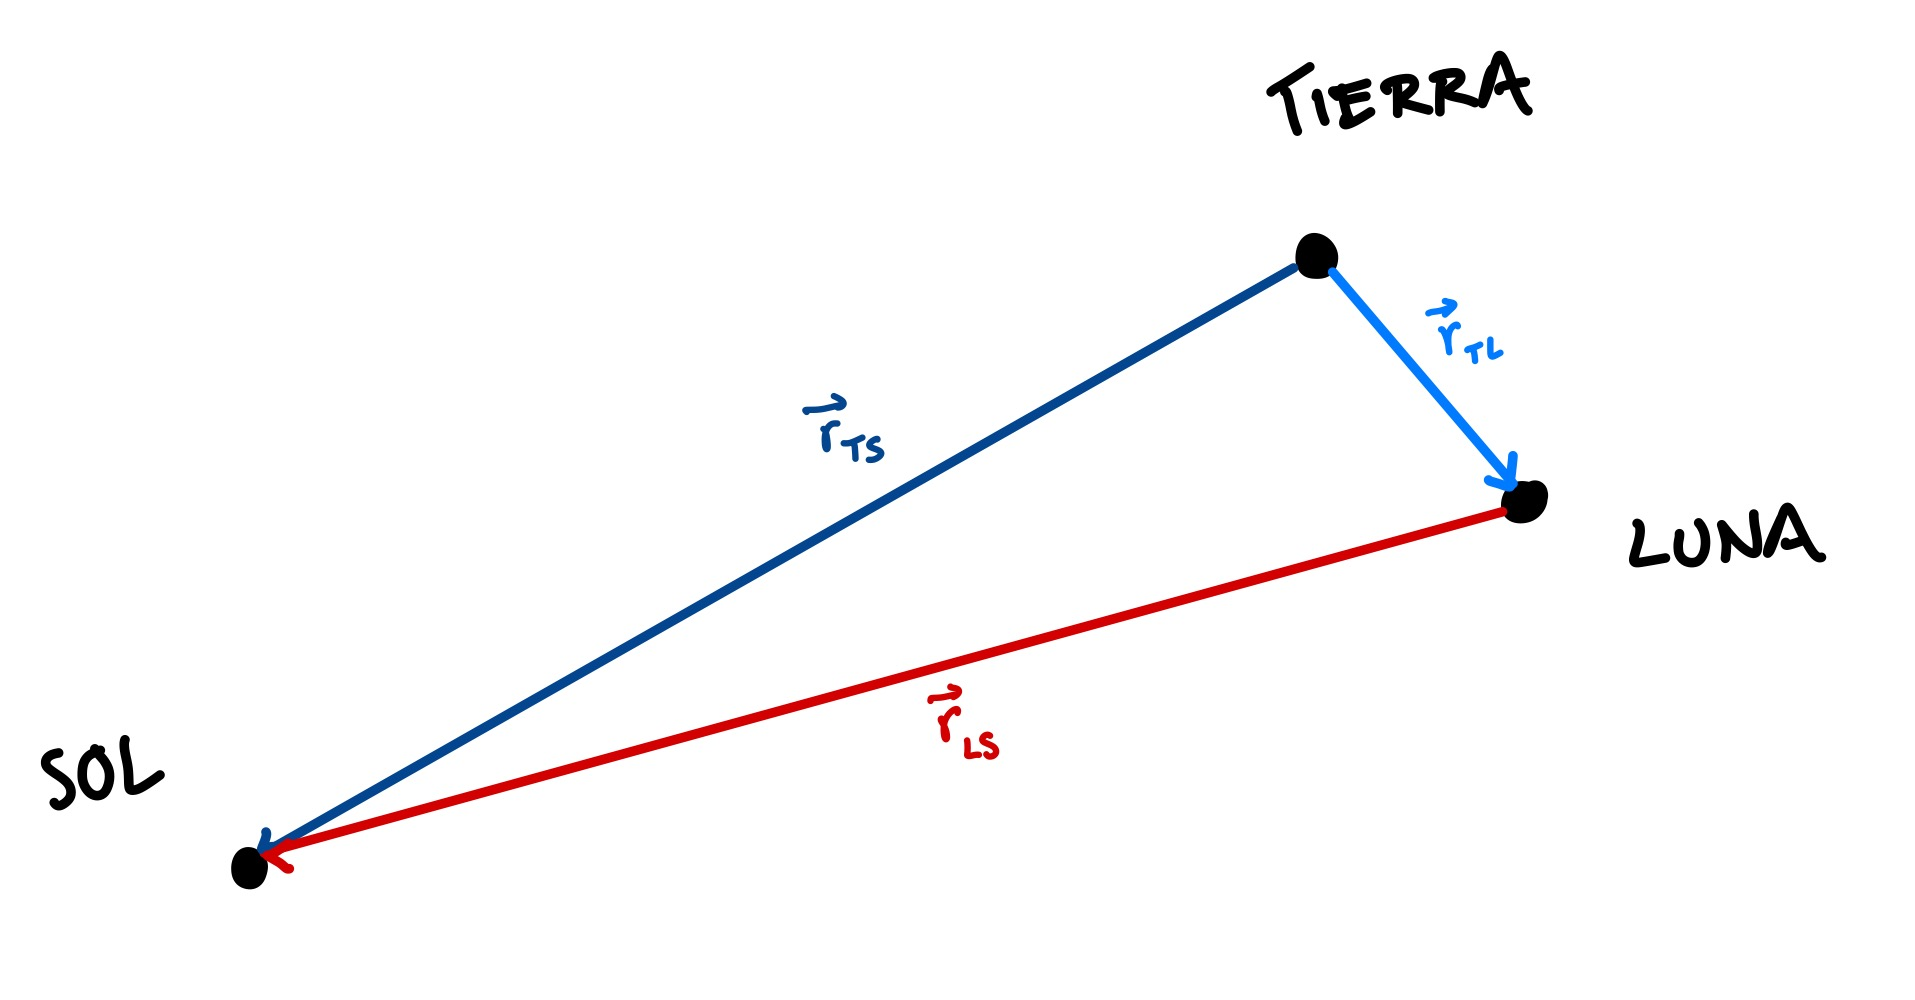

La segunda ley de Newton establece que la aceleración de un objeto es directamente proporcional a la fuerza que actúa sobre él e inversamente proporcional a su masa. Esta ley se representa matemáticamente como:


$$F=m*a\Longrightarrow a=\frac{F}{m}$$


La tercera ley de Newton establece que para cada acción hay una reacción igual y en el sentido opuesto. En nuestro proyecto, esta ley se representa matemáticamente como:

$F_{\textrm{TL}\;} =-F_{\textrm{LT}}$  --> Fuerzas Tierra-Luna

$F_{\textrm{TS}\;} =-F_{\textrm{ST}}$  --> Fuerzas Tierra-Sol

$F_{\textrm{LS}\;} =-F_{\textrm{SL}}$  --> Fuerzas Luna-Sol

Para resolver ecuaciones diferenciales numéricamente, debemos especificar condiciones iniciales. En este caso, deberemos usar las posiciones y velocidades iniciales de los 3 cuerpos celestes.

## Resultados

### Datos

%------------------------------
Rt0 = [8.985042357647341E+07;
      1.162821966958993E+08;
      2.500978715314716E+04];
Vt0 = [-2.397024320548893E+01;
      1.820942848857169E+01;
      -1.773321453848453E-04];
%------------------------------
Rl0 = [8.973100834871185E+07;
      1.159214050926853E+08;
      -4.517218080535531E+02
    ];
Vl0 = [-2.297590864850715E+01;
      1.792406891719226E+01;
      -6.133432693701124E-02];
%------------------------------
Rs0 = [-1.224950680604303E+06;
      -3.836347431650739E+05;
      3.175734887987378E+04];
Vs0 = [7.758131903041959E-03;
      -1.296095373836615E-02;
      -6.466924756494755E-05];
%------------------------------
RV0 = [Rt0;
       Rl0;
       Rs0;
       Vt0;
       Vl0;
       Vs0];
%------------------------------
h = 30;
tspan = [0 60*60*24*365];
rTol = eps;

### Pruebas

tic;
[T, Y] = ode113(@ecuaciones,tspan,RV0);
a = toc;
tic;
[T, Y] = ode45(@ecuaciones,tspan,RV0);
b = toc;
tic;
[T, Y] = ode45m(@ecuaciones,tspan,RV0,h,rTol); 
c = toc;
%tic;
%[T, Y] = RK4(@ecuaciones, tspan, RV0, h); 
%d = toc;
%tic;
%[T, Y] = ABM4V(@ecuaciones,RV0,tspan,h);  
%e = toc;

disp(['RK4: ', num2str(a), ' segundos.']);

RK4: 0.052766 segundos.


disp(['RKF45: ', num2str(b), ' segundos.']);

RKF45: 0.019545 segundos.


disp(['ABM4V: ', num2str(c), ' segundos.']);

ABM4V: 53.8121 segundos.


%disp(['ode45 MATLAB: ', num2str(d), ' segundos.']);
%disp(['ode113 MATLAB: ', num2str(e), ' segundos.']);

### Gráfica

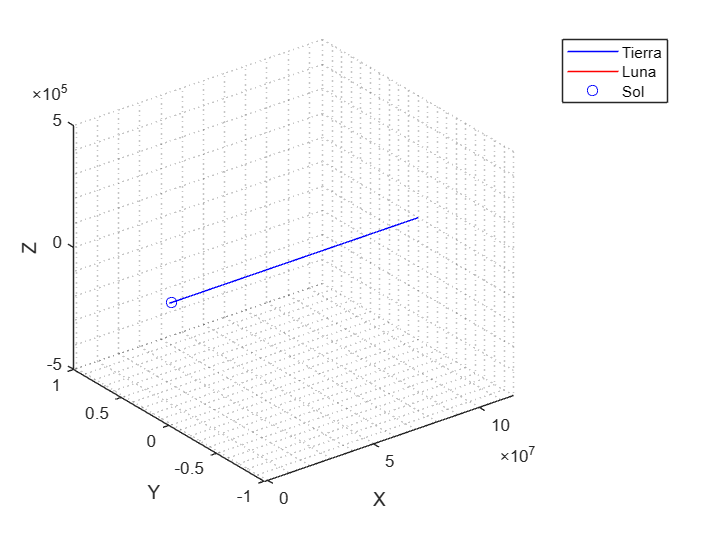

figure;
% plot3(Y(1,:), Y(2,:), Y(3,:), 'b'); % Trayectoria de la Tierra
% hold on;
% plot3(Y(4,:), Y(5,:), Y(6,:), 'r'); % Trayectoria de la Luna
% plot3(Y(7,:), Y(8,:), Y(9,:), 'ob'); % Trayectoria del Sol
plot3(Y(:,1), Y(:,2), Y(:,3), 'b'); 
hold on;
plot3(Y(:,4), Y(:,5), Y(:,6), 'r'); 
plot3(Y(:,7), Y(:,8), Y(:,9), 'ob');
zlim([-0.5e6 0.5e6]);
xlabel('X');
ylabel('Y');
zlabel('Z');
legend('Tierra', 'Luna', 'Sol');
grid minor
hold off

## Conclusiones

¿La Luna gira alrededor de la Tierra o del Sol?

Aunque la Luna está mucho más cerca de la Tierra y por ello se podría esperar que la fuerza gravitatoria terrestre domine, la realidad es que la fuerza gravitatoria mutua entre el Sol y la Luna es más grande que la existente entre la Luna y la Tierra��. Esto se debe a las enormes diferencias en masa entre el Sol y la Tierra, pese a la diferencia en la distancia.

norm(FLS) %Fuerza entre la luna y el sol

Unrecognized function or variable 'Rv'.

norm(FTL) %Fuerza entre la tierra y la luna

Como se observa, la fuerza que ejerce el Sol sobre la Luna es más del doble que la que ejerce la Tierra. El Sol jala a ambos, pero de alguna forma, están "cayendo" juntos.

¿Cómo es la trayectoria que sigue la Luna durante un año? 

A lo largo de un año, la Luna completa múltiples órbitas alrededor de la Tierra. Cada una de estas órbitas se superpone a la trayectoria de la Tierra alrededor del Sol. Al rastrear la trayectoria de la Luna alrededor del Sol, vemos una orbita de curvas senoidales que forman una línea ondulada alrededor del Sol. Esta línea ondulada resulta de la sobreposición de la órbita elíptica de la Luna alrededor de la Tierra con la órbita elíptica de la Tierra alrededor del Sol.

plot(Y(1,:), Y(2,:),'b');
hold on
plot(Y(4,:), Y(5,:),'r');
grid minor
xlim([-1.55e8 -1.35e8]);
ylim([-0.5e8 0.5e8]);
legend('Tierra', 'Luna');

En este tramo de la gráfica, podemos observar que, a diferencia de la órbita elíptica de la Tierra alrededor del Sol, la órbita de la Luna ondula en torno a la de la Tierra mientras gira alrededor del Sol.

¿La órbita de la Luna es convexa?

La órbita de la Luna respecto al Sol no es estrictamente convexa ni cóncava. Es una combinación  de ambas debido a la sobreposición de la órbita lunar alrededor de la Tierra y la órbita terrestre alrededor del Sol.

Eficiencia de los métodos

El RK4 y rkf45 debido a que realiza menos operaciones por paso, resulta más rápido que los demás, aunque requiere más pasos para alcanzar una solución precisa. En contraste, los métodos de orden superior como ode113, ode45 o abm4v tienden a ser más precisos con menos pasos, aunque su implementación involucra un mayor costo computacional. Por el tipo de problema decidimos utilizar una h chica con relacion a nuestro tiempo de muestreo, por lo que los métodos que realizan menos operaciones por paso (RK4 y RKF45) fueron los que menos tradaron. En conclusión, emplear un tamaño de paso "h" más chico suele mejorar el tiempo de cálculo con los métodos RK4 y RKF45, sin embargo, con los otros métodos utilizados conlleva un aumento considerable en el tiempo de cálculo, ya que implica realizar más pasos para completar la integración. 

## Implementacion

### Ecuaciones

function dYdt = ecuaciones(~,Rv)
    GMt = 398600.435436;
    GMl = 4902.800066;
    Ml = 7.349*10^22;
    Mt = 5.97219*10^24;
    Ms = 1988500*10^24;
    r = Rv(1:9);
    v = Rv(10:18);
    drTL = r(4:6) - r(1:3);
    drTS = r(7:9) - r(1:3);
    drLS = r(7:9) - r(4:6);
    uTL = drTL/norm(drTL);
    uTS = drTS/norm(drTS);
    uLS = drLS/norm(drLS);
    drTL2 = norm(drTL)^2;
    drTS2 = norm(drTS)^2;
    drLS2 = norm(drLS)^2;
    FTL = (GMt*Ml/drTL2) * uTL;
    FTS = (GMt*Ms/drTS2) * uTS;
    FLS = (GMl*Ms/drLS2) * uLS;
    a = [(FTL+FTS)/Mt; (-FTL+FLS)/Ml; (-FTS-FLS)/Ms];
    dYdt = [v;a];
end

### RK4

function [t, y] = RK4(f, tspan, y0, h)
    t = tspan(1):h:tspan(2);
    n = length(t);
    m = length(y0);
    y = zeros(m, n);
    y(:, 1) = y0;

    for i = 1:n-1
        k_1 = f(t(i), y(:, i));
        k_2 = f(t(i) + 0.5 * h, y(:, i) + 0.5 * h * k_1);
        k_3 = f(t(i) + 0.5 * h, y(:, i) + 0.5 * h * k_2);
        k_4 = f(t(i) + h, y(:, i) + k_3 * h);
        y(:, i+1) = y(:, i) + (1/6) * (k_1 + 2*k_2 + 2*k_3 + k_4) * h;
    end
end

### RKF45

function [t, y] = ode45m(f, tspan, y0, h, rTol)
    q = 5;
    mu = 0.9;
    t = tspan(1):h:tspan(2);
    y = zeros(length(y0), length(t));
    y(:,1) = y0;

    i = 1;
    while i < length(t)
        if t(i) + 1.1 * h >= tspan(2)
            h = tspan(2) - t(i);
        end

        [z, err] = rkf4step(f, t(i), y(:, i), h);

        if err < rTol
            y(:, i+1) = z;
        else
            h = h * mu * nthroot(rTol / err, q);
        end
        i = i + 1;
    end
end

function [y, err] = rkf4step(f, t, w, h)
    s1 = f(t, w);
    s2 = f(t + (1/4)*h, w + (1/4)*h*s1);
    s3 = f(t + (3/8)*h, w + (3/32)*h*s1 + (9/32)*h*s2);
    s4 = f(t + (12/13)*h, w + (1932/2197)*h*s1 + (7200/2197)*h*s2 - (7296/2197)*h*s3);
    s5 = f(t + h, w + (439/216)*h*s1 - 8*h*s2 + (3680/513)*h*s3 - (845/4104)*h*s4);
    s6 = f(t + (1/2)*h, w - (8/27)*h*s1 + 2*h*s2 - (3544/2565)*h*s3 + (1859/4104)*h*s4 -(11/40)*h*s5);

    w = w + h * ((25/216)*s1 + (1408/2565)*s3 + (2197/4104)*s4 - (1/5)*s5);
    z = w + h * ((16/135)*s1 + (6656/12825)*s3 + (28561/56430)*s4 - (9/50)*s5 + (2/55)*s6);
    err = norm((z - w) ./ z, inf);

    y = z;
end

### ABM4

function [t,y] = ABM4V(f,y0,tspan,h)
    t0 = tspan(1);
    tf = tspan(2);
    t = t0:h:tf;
    n = length(t);
    y = zeros(length(y0),n);
    steps = 4;
    vcp = [-9;37;-59;55];
    vcc = [1;-5;19;9];

    [t(1:steps), y(:,1:steps)] = RK4(f,[t0,t(steps)],y0, h);
    fv = bsxfun(f,t(1:steps),y(:,1:steps));

    for i = steps:n-1
        % predictor
        y(:,i+1) = y(:,i) + (h/24)*(fv*vcp);
        fv(:, 1:3) = fv(:,2:4);
        fv(:,4) = f(t(i+1), y(:,i+1));

        % corrector
        y(:,i+1) = y(:,i) + (h/24)*(fv*vcc);
        fv(:,4) = f(t(i+1), y(:,i+1));
    end
end

## Referencias

- Colaboradores de Wikipedia. (2023, 9 noviembre). Leyes de Newton. Wikipedia, la enciclopedia libre. [https://es.wikipedia.org/wiki/Leyes_de_Newton](https://es.wikipedia.org/wiki/Leyes_de_Newton)

- NASA. (16 de 11 de 2023). Jet Propulsion Laboratory. Obtenido de [https://ssd.jpl.nasa.gov/horizons/app.html#/](https://ssd.jpl.nasa.gov/horizons/app.html#/)

- Colaboradores de Wikipedia. (2023b, noviembre 15). Ley de gravitación Universal. Wikipedia, la enciclopedia libre. [https://es.wikipedia.org/wiki/Ley_de_gravitaci%C3%B3n_universal](https://es.wikipedia.org/wiki/Ley_de_gravitaci%C3%B3n_universal)

- Njeunje, J., & Sewwandi de Silva, D. (7 de 5 de 2018). The equations of planetary motion and their numerical solution.